# Solution to Exercise 7 in *Orbital-Free DFT*

## Radial OFDFT Equation

Euler-Lagrange equation for $u (r ) = r\xi(r) =r\sqrt{\rho(r )}$, for atoms with spherically symmetric ground state electron density, was derived in live script *Orbital-Free DFT* and looks 


$$\hat\mathcal{H}_r u(r)=\mu u(r), \qquad (1)$$


with 


$$\hat \mathcal{H}_r=-\frac{\lambda}{2}\frac{\partial^2}{\partial r^2} +\underline{V_{eff}\,[\rho](r )}= -\frac{\lambda}{2}\frac{\partial^2}{\partial r^2} +\underline{ V_{\mathrm{TF}}[\rho](r ) +  V_{\mathrm{ext}}(r )+ V_{\mathrm{H}}[\rho](r ) +V_{\mathrm{xc}}[\rho](r )}.$$


Solution of Eq. (1) is unique, due to requirement $u(r )\ge 0$ (in 1D only ground state does not have nodes), and it is necessarily the ground state of Hamiltonian $\hat\mathcal{H}_r$.

Using self-consistent field algorithm, sketched in Fig. 1, in this live script we will iteratively obtain ground state of Hamiltonian $\hat\mathcal{H}_r$, starting from some initially guessed ground state electron density $\rho_0(r )$. 

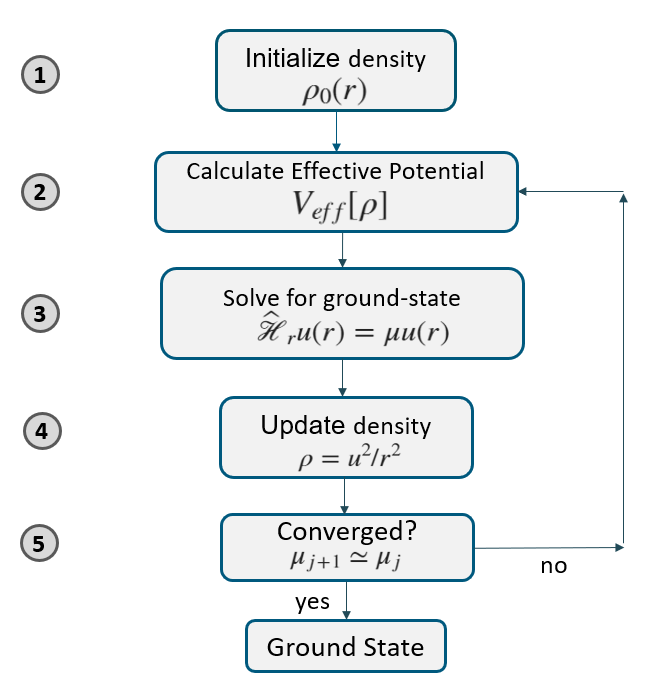

Figure 1: Sketch of numerical algorithm of self-consistent field method.

## OFDFT Numerical Results 

We start with selecting parameters for simulating ground state energy and electron density of atoms using the OFDFT solver based on self-consistent field method sketched in Fig. 1. We will compare OFDFT resutls with the TF results. 

See live script on *Thomas-Fermi Approximation* where we saved structure variable `TFchi`, with `TFchi.x` and `TFchi.y` containing values of $x$ and $\chi(x)$ - the universal parameter and  the universal TF function respectively.

load TFchi.mat;   

 First we select the atom index $Z$, maximal radial length $R_{max}$, measured in Bohr radia, and number of grid points $N_d$ in radial direction. Since in the TF model atom radius shrinks as $Z^{-1/3}$ wih increasing nuclear charge, and since densities produced by our OFDFT solver are not far from the TF results for large $Z$, we rescale $R_{max}$ with the same factor.

Z = 4; 
R_MAX = 60/Z^(1/3);
Nd=1200;

Next, we determine whether we allow the mixing of von Weizsäcker functional with non-zero parameter $\lambda$ and use LDA-PZ (Local Density Approximation with Perdew-Zunger expression for correlation term) exchange-correlation (xc). When `xc=lda` is selected, $\lambda \simeq 0.212$ is a good choice for calculating ground state energies of atoms with $Z>1$, for number of grid points in radial direction $N_d$ up to $1200$ sites and $R_{max}=60/Z^{1/3}$.

lambda=0.212;
xc = 1;

Finally, we set up FDn - order for approximating derivatives by [central finite differences](https://en.wikipedia.org/wiki/Finite_difference), convergence tolerance `tol`, and density-mixing parameter `beta`. 

FDn = 6; 
tol = 1e-3;
beta=0.95; 

Now we start our radial OFDFT simulation that is included and explained at the end of this script. We use the TF density profile for initial electron density. 

fprintf("Analytical Thomas-Fermi energy for Z=%.d is %.4f Ha\n", Z, -0.7687*Z^(7/3));

Analytical Thomas-Fermi energy for Z=4 is -19.5238 Ha


r_x = TFchi.x*Z^(-1/3)/1.1295; % see Eq. (32) in live script Thomas-Fermi Approximation, where we saved variable TFchi
rho_r_x = 32/9/pi^3*(TFchi.y./TFchi.x).^(3/2)*Z^2; % see Eq. (35) in live script Thomas-Fermi Approximation 

S_OFDFT = init_OFDFT(Z,R_MAX,Nd,tol,FDn,lambda,xc,[r_x, rho_r_x],beta); 
S_OFDFT = SCF(S_OFDFT); % run self-consistent field algorithm

Finished SCF method in 25 steps with μ = -0.2495
Energy decomposition 
Ek   =  13.372909 Ha
Eh   =   6.987292 Ha
Exc  =  -2.407369 Ha
Ex  =  -2.178815 Ha
Ec  =  -0.228554 Ha
Eext = -32.554199 Ha
Etot = -14.601367 Ha, -397.323757 eV


After the electron density $\rho(r)$ is converged, we plot radial electron density $4\pi\rho( r)r^2$ as a function of distance from the nucleus (measured in units of Bohr radius), together with the TF result (that we loaded in variable` TFchi`).

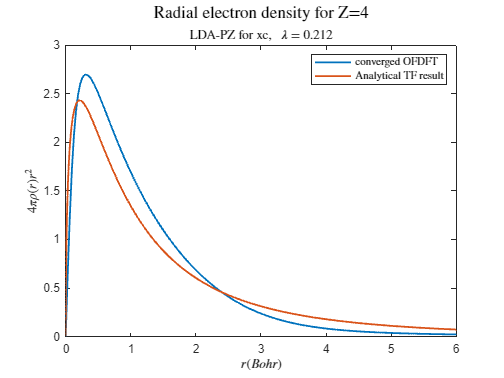

plot([0;S_OFDFT.r],[0;4*pi*S_OFDFT.rho.*S_OFDFT.r.^2],r_x,4*pi*rho_r_x.*r_x.^2)
xlabel("$r (Bohr)$",Interpreter='latex')
ylabel("$4\pi \rho(r) r^2$",Interpreter='latex')
xlim([0 6])
legend("converged OFDFT","Analytical TF result",Interpreter='latex')
title(['Radial electron density for Z=',num2str(Z)],'Interpreter','latex', fontsize=14)
if xc==1
    subtitle(['LDA-PZ for xc, \,\, $\lambda=$',num2str(lambda)],Interpreter='latex')
else
    subtitle(['No xc, \,\, $\lambda=$',num2str(lambda)],Interpreter='latex')
end

Next, we plot the radial dependence of 

- External potential $V_{\mathrm{ext}}(r )$ 

and of the converged values of (for converged $\rho$):

- The TF potential $V_{\mathrm{TF}}[\rho](r)$ 

- Hartree potential $V_{\mathrm{H}}[\rho](r )$  

- Exchange-correlation potential $V_{\mathrm{xc}}[\rho](r )$ (if selected) 

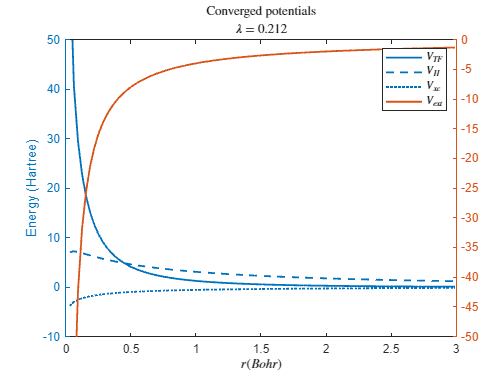

figure
yyaxis left
plot(S_OFDFT.r,S_OFDFT.Vtf,S_OFDFT.r,S_OFDFT.Vh)
if S_OFDFT.xc == 1
    hold on
    plot(S_OFDFT.r,S_OFDFT.Vx+S_OFDFT.Vc);
    hold off
end
ylim([-10 50])
ylabel("Energy (Hartree)")
yyaxis right
plot(S_OFDFT.r,S_OFDFT.Vext)
ylim([-50 0])
if S_OFDFT.xc == 1
    legend("$V_{TF}$","$V_H$","$V_{xc}$","$V_{ext}$",Interpreter='latex')
else
    legend("$V_{TF}$","$V_H$","$V_{ext}$",Interpreter='latex')
end
xlabel("$r (Bohr)$",Interpreter='latex')
xlim([0 3])
title("Converged potentials",Interpreter='latex')
if xc==1
    subtitle(['$\lambda=$',num2str(lambda)],Interpreter='latex')
else
    subtitle(['No xc, \,\, $\lambda=$',num2str(lambda)],Interpreter='latex')
end
box on
hold off

Next, for the case when xc is activated, we plot separately radial dependence of exchange and correlation potentials to see which contribution is dominant. 

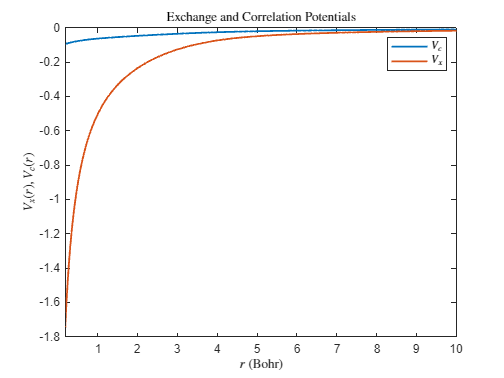

if xc==1
    figure
    plot( S_OFDFT.r ,S_OFDFT.Vc,S_OFDFT.r,S_OFDFT.Vx)
    legend("$V_{c}$","$V_{x}$",Interpreter='latex')
    xlim([0.2,10])
    ylabel("$V_{x}(r),V_{c}(r) $",Interpreter='latex')
    xlabel("$r$ (Bohr)",'Interpreter','latex')
    title( "Exchange and Correlation Potentials",Interpreter='latex')
end

And lastly we plot the converged effective potential $V_{\mathrm{eff}}[\rho_{converged}](r)=V_{TF}+V_{\mathrm{ext}}+V_\mathrm{H}+\mathrm{xc}(V_{\mathrm{x}}+V_{\mathrm{c}})$

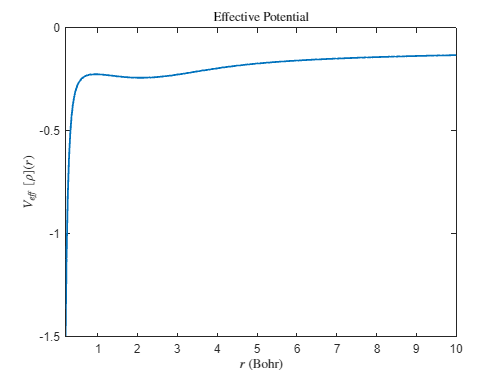

figure
plot(S_OFDFT.r,S_OFDFT.Veff)
xlim([0.2,10])
ylabel("$V_{eff}\,\,[\rho](r)$",Interpreter='latex')
xlabel("$r$ (Bohr)",Interpreter='latex')
title( "Effective Potential",Interpreter='latex')

## Self-Consistent Field method for radial OFDFT

We start by implementing action of Hamiltonian $\hat \mathcal{H}_r$ ($N_d$x$N_d$ matrix) on vector.

function Hr_u = Hamiltonian(S,u)
% Hamiltonian times vector routine

    Hr_u = - S.lambda/2*S.Lap*u + S.Veff.*u;
end

Next we implement effective potential.

function S = compute_effective_potential(S,rho)
% After S=compute_effective_potential(S,rho) -> structure S 
% picks up additional fields, various potentials, including effective potential. 
    
    S.Vtf = (5/3)*S.Cf*rho.^(2/3);
    S.Vh = compute_hartree_potential(S,rho);
    S.Veff = S.Vtf + S.Vext + S.Vh;
    
    if S.xc == 1
        rho(rho < 1e-10) = 1e-6;
        [S.Ex,S.Vx] = slater(rho);
        [S.Ec,S.Vc] = pz(rho);
        % total potential 
        S.Veff = S.Veff + S.Vx + S.Vc;  % complete effective potential when xc is activated
    end
end

Next we impement Hartree potential.

function Vh = compute_hartree_potential(S,rho)
  
    phi = S.Lap\(-4*pi*rho.*S.r); % note the left divide sign mldivide \ 
    Vh = phi./S.r;
end

Helper function to convert 3D integrals to 1D radial sum for spherically symmetric functions. 

function intf = int3d(S,f)
% Computes integral of function in R3 in spherical coordinates assuming f is spherically symmetric
    intf = 4*pi*S.h*sum(f.*S.r.^2);
end

The total energy expressed in terms of $u(r)$ 


$$\begin{array}{cc}\begin{array}{rll}E =& T_{\mathrm{TF}} + \lambda T_{\mathrm{vW}}(\rho) + E_{\mathrm{ext}} + E_{\mathrm{xc}} + E_{\mathrm{H}} \\=& 4\pi C_F \int u^{10 / 3}(r)/r^{4/3}d r  - 2 \pi \lambda \int u(r) u''(r) dr \\&- 4\pi \int \frac{Z}{r} u^2(r) dr +  4 \pi \int \epsilon_{\mathrm{xc}}(r) u^2(r) dr + 2 \pi \int V_{\mathrm{H}}(r) u^2(r) dr\end{array}& \\ \end{array}$$


function S = energy(S)
% After S=energy(S) -> structure S picks up additional fields, 
% various energies, including total energy.
    
    S.Ek = S.Cf * int3d(S,S.rho.^(5/3)) - S.lambda/2*int3d(S,S.u.*(S.Lap*S.u)./S.r.^2);
    S.Eh = 0.5*int3d(S,S.Vh.*S.rho);
    S.Eext = int3d(S,S.Vext.*S.rho);
    S.Etot = S.Ek + S.Eh + S.Eext;
    if S.xc == 1
        S.Exc = int3d(S,(S.Ex+S.Ec).*S.rho);
        S.Exchange=int3d(S,S.Ex.*S.rho);
        S.Ecorr=S.Exc-S.Exchange;
        S.Etot = S.Etot + S.Exc;
    end
end

The normalization condition $\int \rho(\mathbf{r}) d\mathbf{r} =4\pi \int \rho(r)r^2 dr=Z$ translates to


$$\begin{array}{cc}4\pi \int u^2(r) dr = Z,& \\ \end{array}$$
 

that we implement numerically after each iteration.

function u = normalize(S,u)
% normalizes u = r * rho^(1/2)
% in order to have the 3D integral of rho equal to Z for a neutral atom
    
    scale = S.Z / (u'*u*4*pi*S.h);   % S.h=dr, integration measure in radial direction
    u = u * sqrt(scale);
    u = abs(u);
end

Initialization function

function S = init_OFDFT(Z,R_MAX,Nd,tol,FDn,lambda,xc,rho0,beta)
    
    S = struct();
    S.Z = Z;
    S.Nd = Nd;
    S.h = R_MAX/(Nd);
    S.r = linspace(S.h,R_MAX,Nd)'; % radial space
    S.FDn = FDn;
    S.tol = tol;
    S.Cf = (3/10)*(3*pi^2)^(2/3);
    S.lambda = lambda;
    S.beta=beta;
    S.xc = xc;  % xc=1 means that we are using LDA-PZ exchange-correlation functional
    
    % energy
    S.Etot = 0; % total energy initially set to 0
    
    % external (nuclear) coulomb potential 
    S.Vext = - S.Z./ S.r; 
    
    % Laplacian matrix in 1D
    S.Lap = Laplacian(S.FDn,S.Nd,S.h);

Now we describe each step of our numerical implementation of Self-Consistent Field methos of radial OFDFT,  sketched in Fig. 1.

Initialize the electron density by using some reasonable guess (we will use Thomas-Fermi result $\rho_0(r)=\rho_{_{TFNA}}(r)$ for initial density), and interpolate it using [`griddedInterpolant`](https://www.mathworks.com/help/matlab/ref/griddedinterpolant.html#d126e628453) function. Interpolation is needed due to a possible mismatch between the mesh of the initial guess and $N_d$ and $R_{max}$ parameters. Here we interpolate $r^2\rho(r)$, which is smoother than $\rho(r)$, by a cubic spline interpolation method.

    % initial electron density 
    x = rho0(:,1);
    rho_r = rho0(:,2);
    r2rho = griddedInterpolant(x, x.^2.*rho_r, 'spline');
    r2rho = r2rho(S.r);
    r2rho(S.r>x(end)) = 0; % interpolate to zero density outside of the initial grid used in guess
    rho0 = r2rho ./S.r.^2;
    S.u = normalize(S,S.r.*sqrt(rho0));
    S.rho= (S.u./S.r).^2;
end

Then we implement the Self-Consistent Field algorithm sketched in Fig. 1.

function S = SCF(S)
    S = compute_effective_potential(S,S.rho); 
    opts = struct(maxit=5000, tol= 1e-5, isreal=1);
    % beta=0.9;  % density mixing parameter
    mu_prev=0;
    mu_next=1;
    j=0;
    while abs(mu_prev-mu_next) > S.tol  
        mu_prev=mu_next;
        Hfun = @(x) Hamiltonian(S,x); 
        [S.u, mu] = eigs(Hfun,S.Nd,1,'smallestreal',opts);
        mu_next=mu;
        S.u = normalize(S,S.u);
        S.rho = (1-S.beta)*(S.u./S.r).^2+S.beta*S.rho;
        S = compute_effective_potential(S,S.rho);
        S = energy(S);
        j=j+1;
    end
    
    fprintf('Finished SCF method in %d steps with \x03bc = %.4f', j+1, mu);
    fprintf("\nEnergy decomposition \n");
    fprintf("Ek   = %10.6f Ha\n", S.Ek);
    fprintf("Eh   = %10.6f Ha\n", S.Eh);
    if S.xc == 1
        fprintf("Exc  = %10.6f Ha\n", S.Exc);
        fprintf("Ex  = %10.6f Ha\n", S.Exchange);
        fprintf("Ec  = %10.6f Ha\n", S.Ecorr);
    end
    fprintf("Eext = %10.6f Ha\n", S.Eext);
    fprintf("Etot = %10.6f Ha, %10.6f eV\n", S.Etot, S.Etot * 27.2114079527);
end

Below are pair of functions (`slater` and `pz`) for implementing LDA exchange and LDA-PZ correlation functional and potential.

function [ex,vx] = slater(rho)
% slater exchange
    
    % rho, electron density
    % ex, exchange energy density 
    % vx, exchange potential 
    
    C2 = 0.73855876638202; % 3/4*(3/pi)^(1/3)
    C3 = 0.9847450218427;  % (3/pi)^(1/3)
    ex = - C2 * rho.^(1./3.);
    vx = - C3 * rho.^(1./3.);
end

function [ec,vc] = pz(rho)
% pz correlation: Perdew-Zunger implementation of LDA correlation energy and potential
    
    % rho, electron density
    % ec, correlation energy density 
    % vc, correlation potential
    
    A = 0.0311;
    B = -0.048;
    C = 0.002;
    D = -0.0116;
    gamma1 = -0.1423;
    beta1 = 1.0529;
    beta2 = 0.3334;
    
    % compuatation
    ec = zeros(size(rho,1),1);
    vc = zeros(size(rho,1),1);
    rs = (0.75./(pi*rho)).^(1.0/3.0) ;
    islt1 = (rs < 1.0);
    lnrs = log(rs(islt1));
    sqrtrs = sqrt(rs(~islt1));
    ec(islt1) = A * lnrs + B + C * rs(islt1) .* lnrs + D * rs(islt1);
    ox = 1.0 + beta1*sqrtrs + beta2*rs(~islt1);
    ec(~islt1) = gamma1 ./ ox;
    vc(islt1) = lnrs.*(A + (2.0/3.0)*C*rs(islt1)) + (B-(1.0/3.0)*A) + (1.0/3.0)*(2.0*D-C)* rs(islt1);
    vc(~islt1) = ec(~islt1) .* (1 + (7.0/6.0)*beta1*sqrtrs + (4.0/3.0)*beta2*rs(~islt1)) ./ ox;
end

Finally, we provide functions for creating discrete Laplacian using central finite difference method. 

%%%%%%% finite difference functions %%%%%%%

function Lap = Laplacian(FDn,Nd,h)
% the sparse 1D Laplacian matrix 
    
    % FDn, half order of accuracy
    % Nd, number of grid points
    % h, mesh 
    
    w2 = w2_c(FDn);
    e = ones(Nd,1)/h^2;
    Lap = spdiags(w2(1)*e,0,Nd,Nd);
    for i = 1:FDn
        Lap = Lap + spdiags(w2(i+1)*e,i,Nd,Nd);
        Lap = Lap + spdiags(w2(i+1)*e,-i,Nd,Nd);
    end
end

function w2 = w2_c(FDn)
% generate central finite difference coefficients for second order derivative
    
    % FDn, half order of accuracy
    % w2, central finite difference coefficients
    
    w2 = zeros(1,FDn+1) ;
    for k=1:FDn
	    w2(k+1) = (2*(-1)^(k+1))*(factorial(FDn)^2)/...
		    (k*k*factorial(FDn-k)*factorial(FDn+k));
	    w2(1) = w2(1)-2*(1/(k*k));
    end
end